close all force

trainDatasetPath = fullfile('Images','train');

imds = imageDatastore(trainDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

labelCount = countEachLabel(imds);

imds.ReadFcn = @(x)imresize(imread(x),[64, 64]);

% show some instances
figure;
perm = randperm(length(imds.Labels),20);
for ii = 1:20
    subplot(4,5,ii);
    imshow(imds.Files{perm(ii)}); 
    title(imds.Labels(perm(ii)));
end

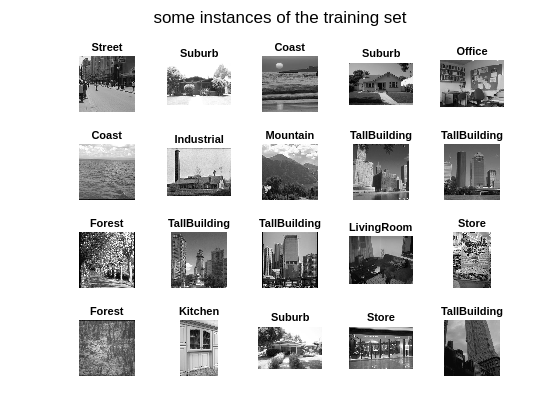

sgtitle('Some instances of the training set')

% split in training and validation sets: 85% - 15%
quotaForEachLabel=0.85;
[imdsTrain,imdsValidation] = splitEachLabel(imds,quotaForEachLabel,'randomize');

%% Network design and training
% Design a basic network, following the given layout.
% Train it and gradually improve the value of the learning rate

layers = [
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    % ,'WeightsInitializer','narrow-normal'
    convolution2dLayer(3,8,'WeightsInitializer','narrow-normal', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(3,16,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_2')
    reluLayer('Name','relu_2')
    
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(3,32,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_3')
    reluLayer('Name','relu_3')
    
    fullyConnectedLayer(15,'WeightsInitializer','narrow-normal','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

    lgraph = layerGraph(layers);
    analyzeNetwork(lgraph)

% Use the stochastic gradient descent with momentum

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ... % this is changed in order to improve the results
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'ValidationPatience',10,... %pazienza (verifica se meglio valorizzare)
    'Verbose',false, ...
    'MiniBatchSize',32, ...
    'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 32
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 10
              ValidationPatience: 10
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: 


% 'ExecutionEnvironment','parallel',...

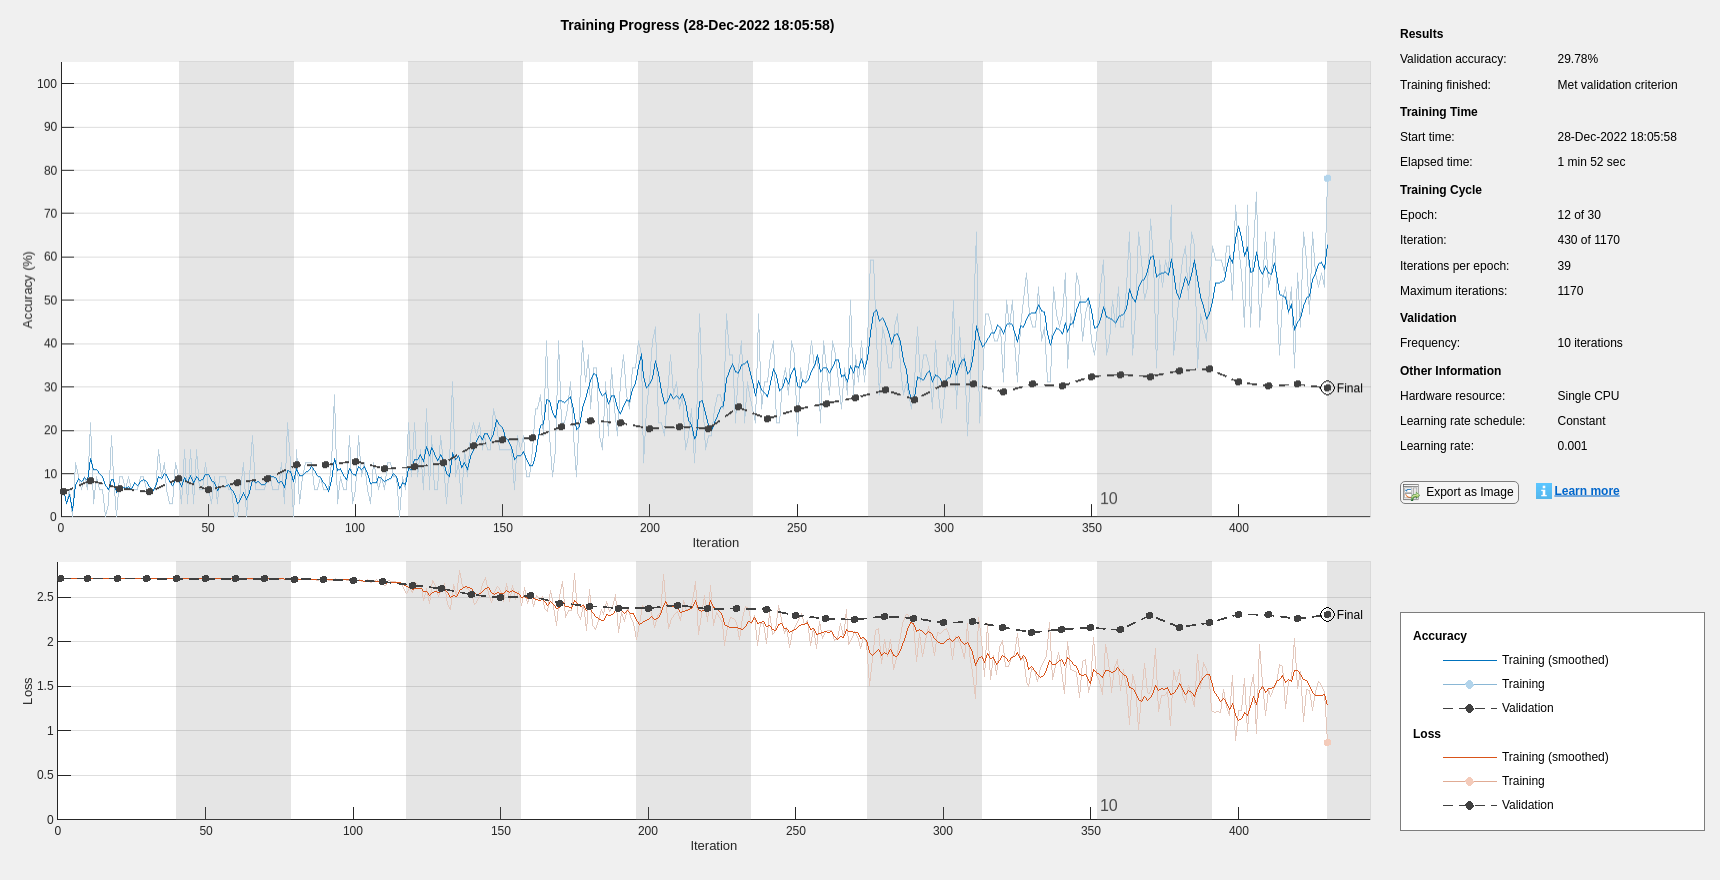

% train the net
net = trainNetwork(imdsTrain,layers,options);

%test the net
testDatasetPath  = fullfile('Images','test');

imdsTest = imageDatastore(testDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
%imdsTest.ReadFcn = @(x)imresize(double(imread(x))/divideby,[64 64]);
imdsTest.ReadFcn = @(x)imresize(imread(x),[64,64]);


% apply the network to the test set
YPredicted = classify(net,imdsTest);
YTest = imdsTest.Labels;

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.3384

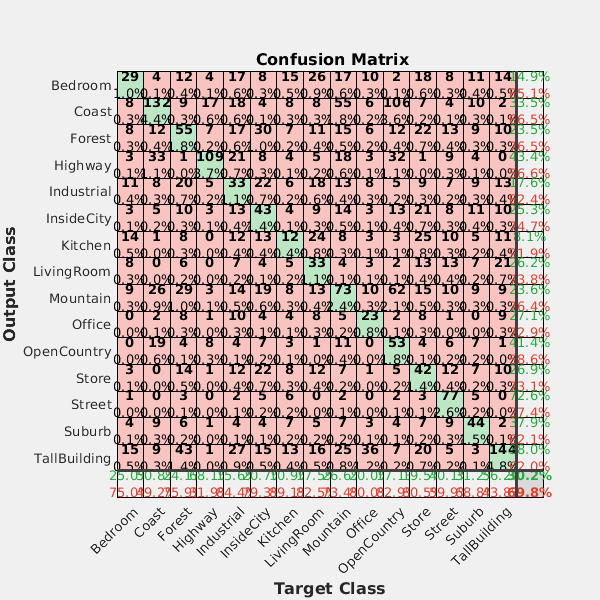


% confusion matrix
figure
plotconfusion(YTest,YPredicted)

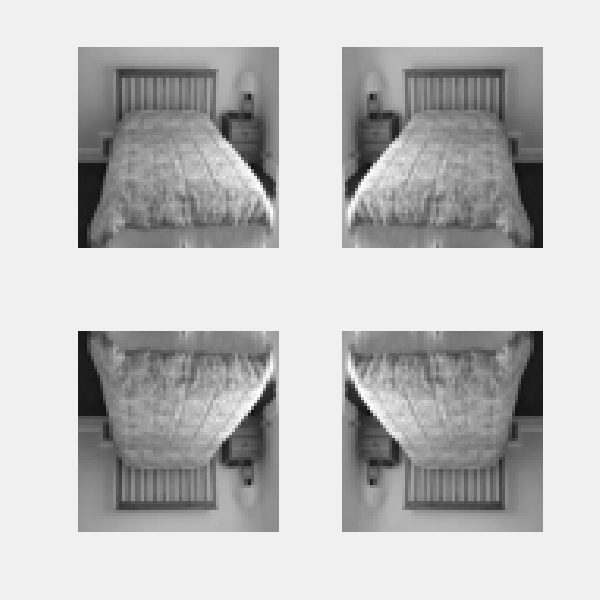

%Now let's try data augmentation by considering the horizontal mirroring of
%the images. The possibilities for mirroring are the following:
iimage=100;
I = imds.readimage(iimage);
I2 = flip(I ,2);           %# horizontal flip
I3 = flip(I ,1);           %# vertical flip
I4 = flip(I3,2);    %# horizontal+vertical flip
subplot(2,2,1), imshow(I)
subplot(2,2,2), imshow(I2)
subplot(2,2,3), imshow(I3)
subplot(2,2,4), imshow(I4)

%For now, we are interested only to the horizontal flip 

aug = imageDataAugmenter('RandXReflection',1);
auimdsTrain = augmentedImageDatastore([64 64 1],imdsTrain,'DataAugmentation',aug);

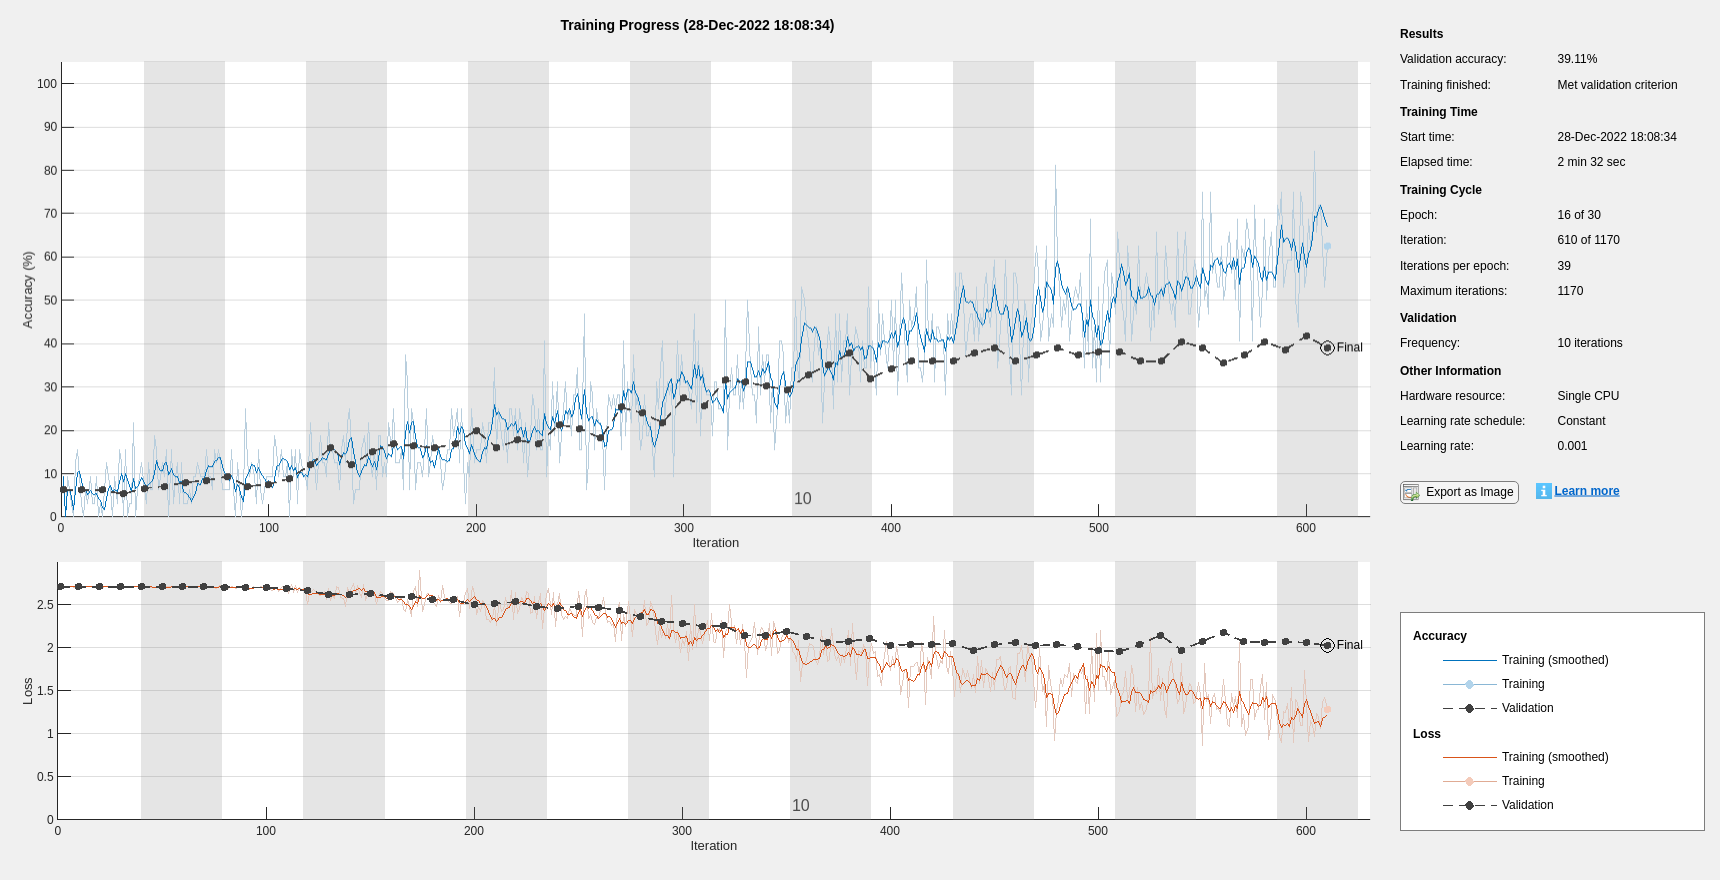



net_1 = trainNetwork(auimdsTrain,layers,options);

% apply the network to the test set
YPredicted = classify(net_1,imdsTest);
YTest = imdsTest.Labels;

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.4137

%Now we try to add batch normalization layers before the reLU layers
layers_2 = [
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    convolution2dLayer(3,8,'WeightsInitializer','narrow-normal', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(3,16,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(3,32,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    
    fullyConnectedLayer(15,'WeightsInitializer','narrow-normal','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

    lgraph = layerGraph(layers_2);

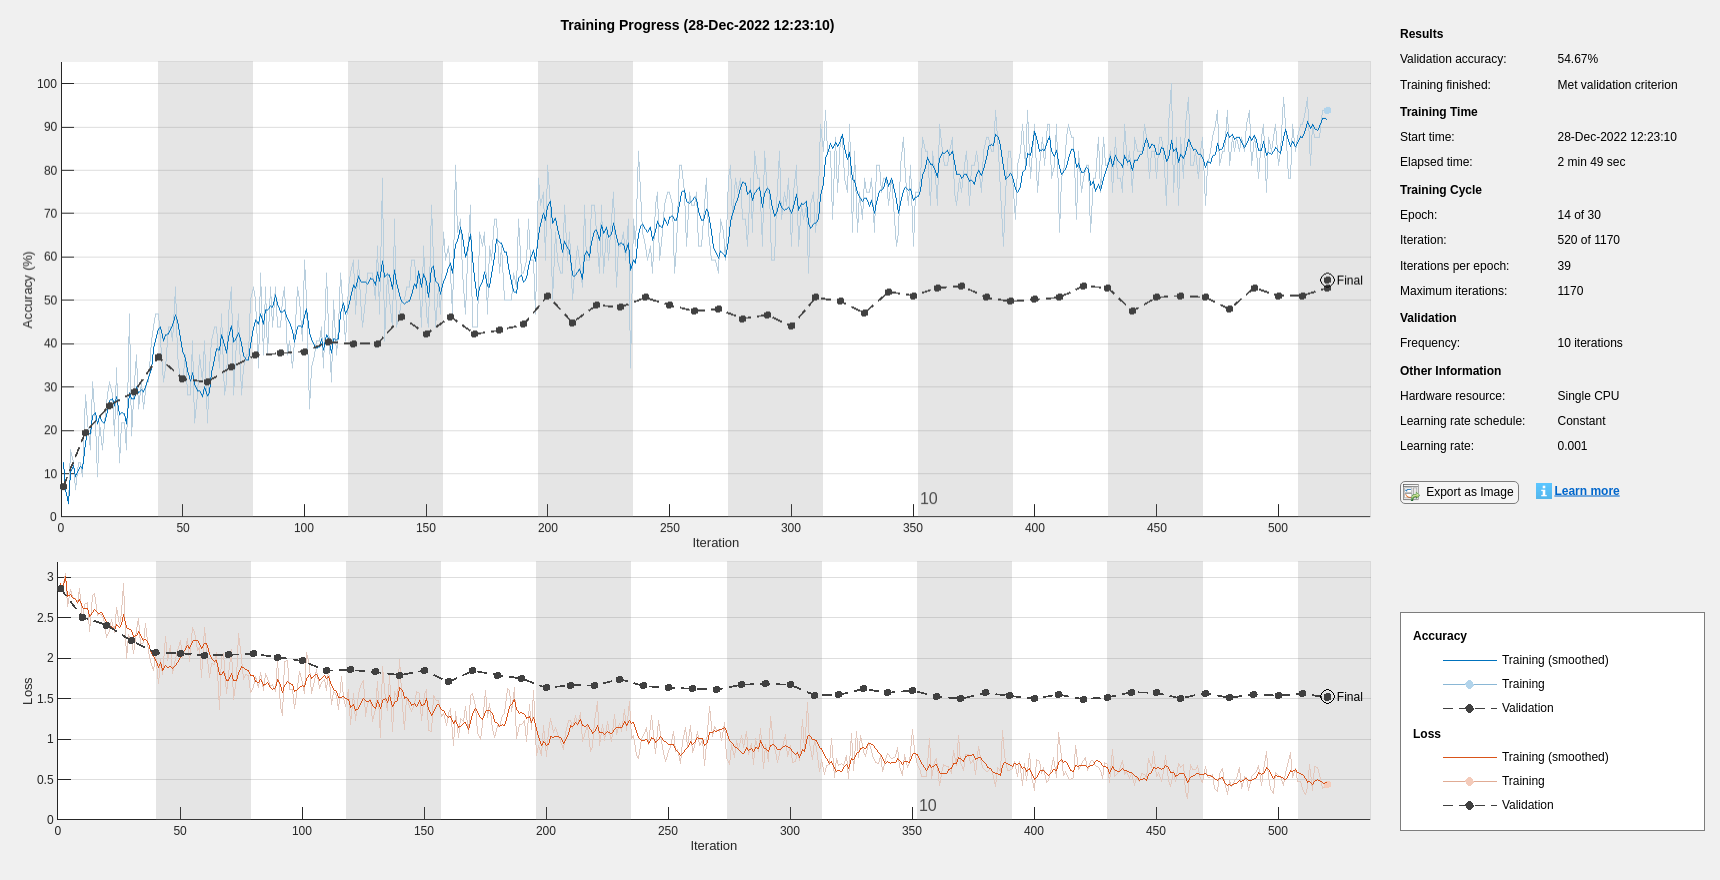

net_2 = trainNetwork(auimdsTrain,layers_2,options);


% apply the network to the test set
YPredicted = classify(net_2,imdsTest);
YTest = imdsTest.Labels;

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.5474

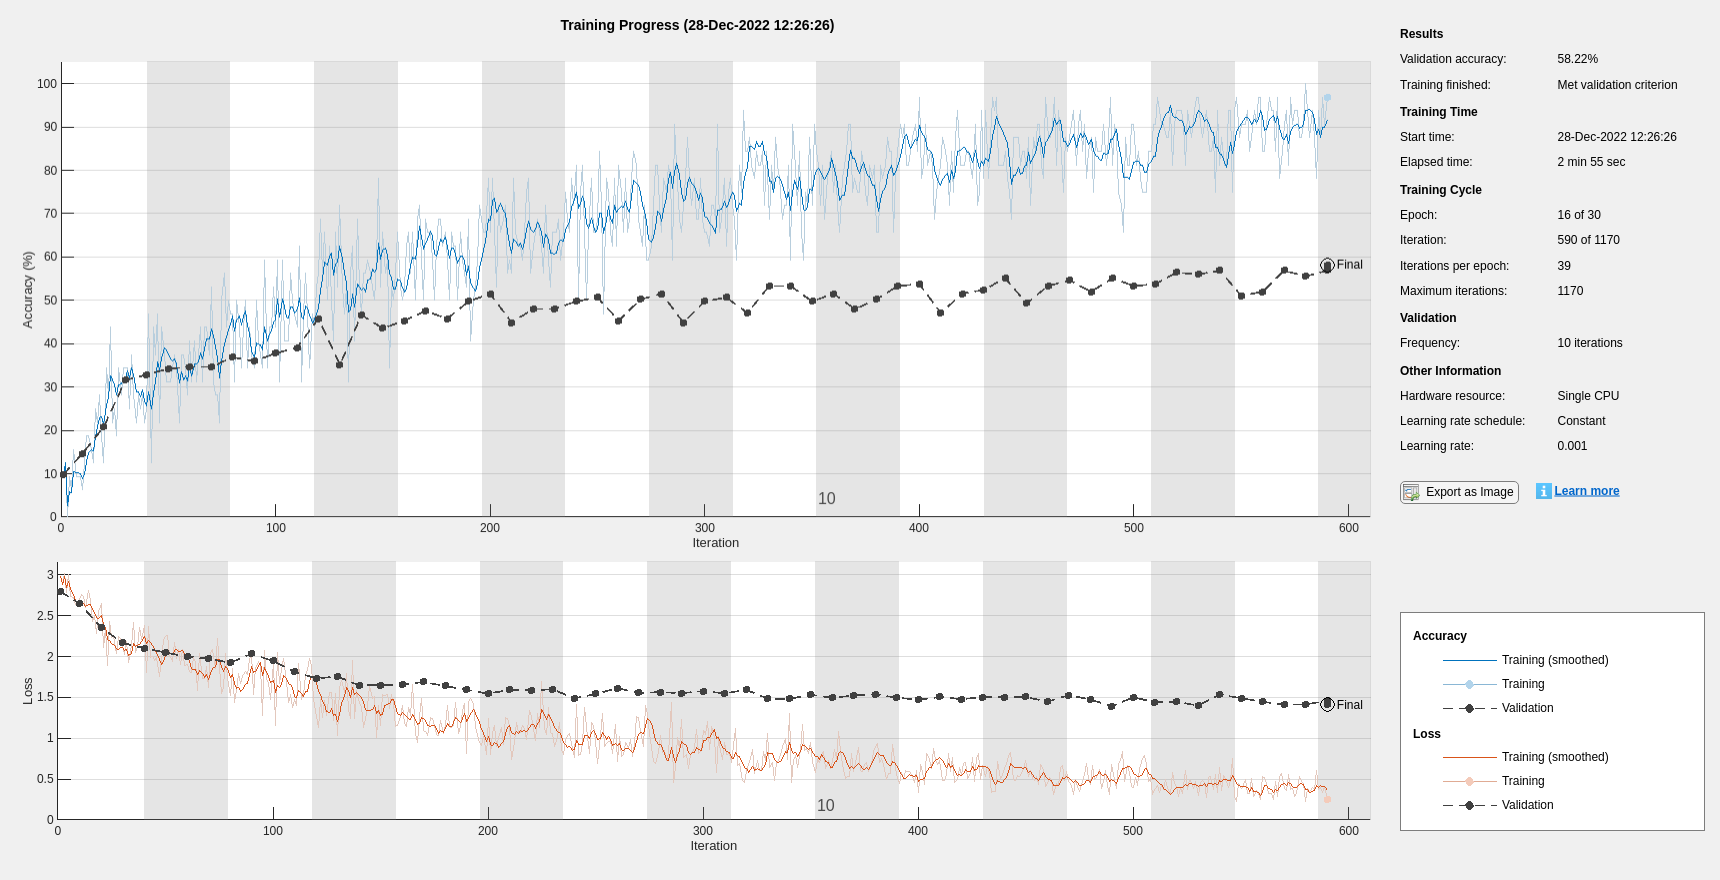

%Change the size of the filters
layers_3 = [    
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    convolution2dLayer(3,8,'WeightsInitializer','narrow-normal', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(5,16,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(7,32,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    
    fullyConnectedLayer(15,'WeightsInitializer','narrow-normal','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

net_3 = trainNetwork(auimdsTrain,layers_3,options);


% apply the network to the test set
YPredicted = classify(net_3,imdsTest);
YTest = imdsTest.Labels;

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.5839

options_2 = trainingOptions('adam', ...
    'InitialLearnRate',0.001, ... % this is changed in order to improve the results
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'ValidationPatience',10,... %pazienza (verifica se meglio valorizzare)
    'Verbose',false, ...
    'MiniBatchSize',32, ...
    'Plots','training-progress')

options_2 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 30
                   MiniBatchSize: 32
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 10
              ValidationPatience: 10
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyU

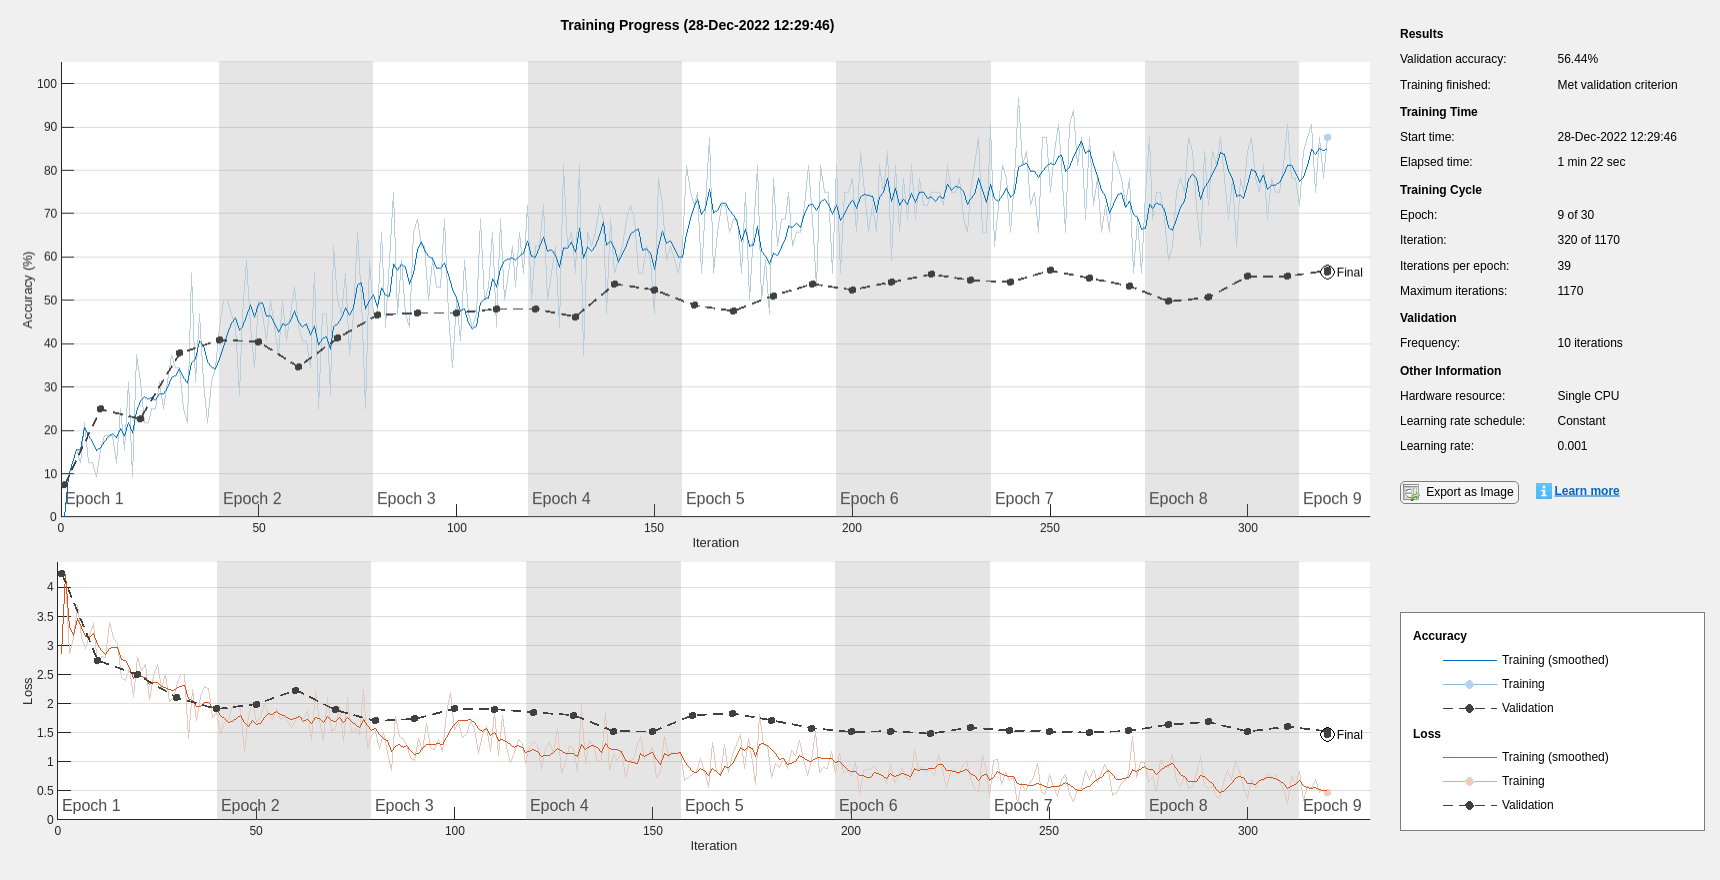

net_4 =   SeriesNetwork with properties:

         Layers: [15×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'output'}



net_4 = trainNetwork(auimdsTrain,layers_3,options_2)


% apply the network to the test set
YPredicted = classify(net_4,imdsTest);
YTest = imdsTest.Labels;

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.5739

%add dropout layers

layers_4 = [    
    imageInputLayer([64 64 1],'Name','input') % 64x64 bw images. 
    convolution2dLayer(3,8,'WeightsInitializer','narrow-normal', 'Padding', 'same' ,'Name','conv_1') %stride 1 is the default
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')
    dropoutLayer('Name','drop1')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_1')
    
    convolution2dLayer(5,16,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    dropoutLayer('Name','drop2')

    maxPooling2dLayer(2,'Stride',2,'Name','maxpool_2')
    
    convolution2dLayer(7,32,'WeightsInitializer','narrow-normal','Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    dropoutLayer('Name','drop3')
    
    fullyConnectedLayer(15,'WeightsInitializer','narrow-normal','Name','fc_1')
    softmaxLayer('Name','softmax')
    
    classificationLayer('Name','output')
    ];

options_3 = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ... % this is changed in order to improve the results
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'ValidationPatience',Inf,... %pazienza (verifica se meglio valorizzare)
    'Verbose',false, ...
    'MiniBatchSize',32, ...
    'MaxEpochs', 15,...
    'Plots','training-progress')

options_3 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 15
                   MiniBatchSize: 32
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 10
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: [

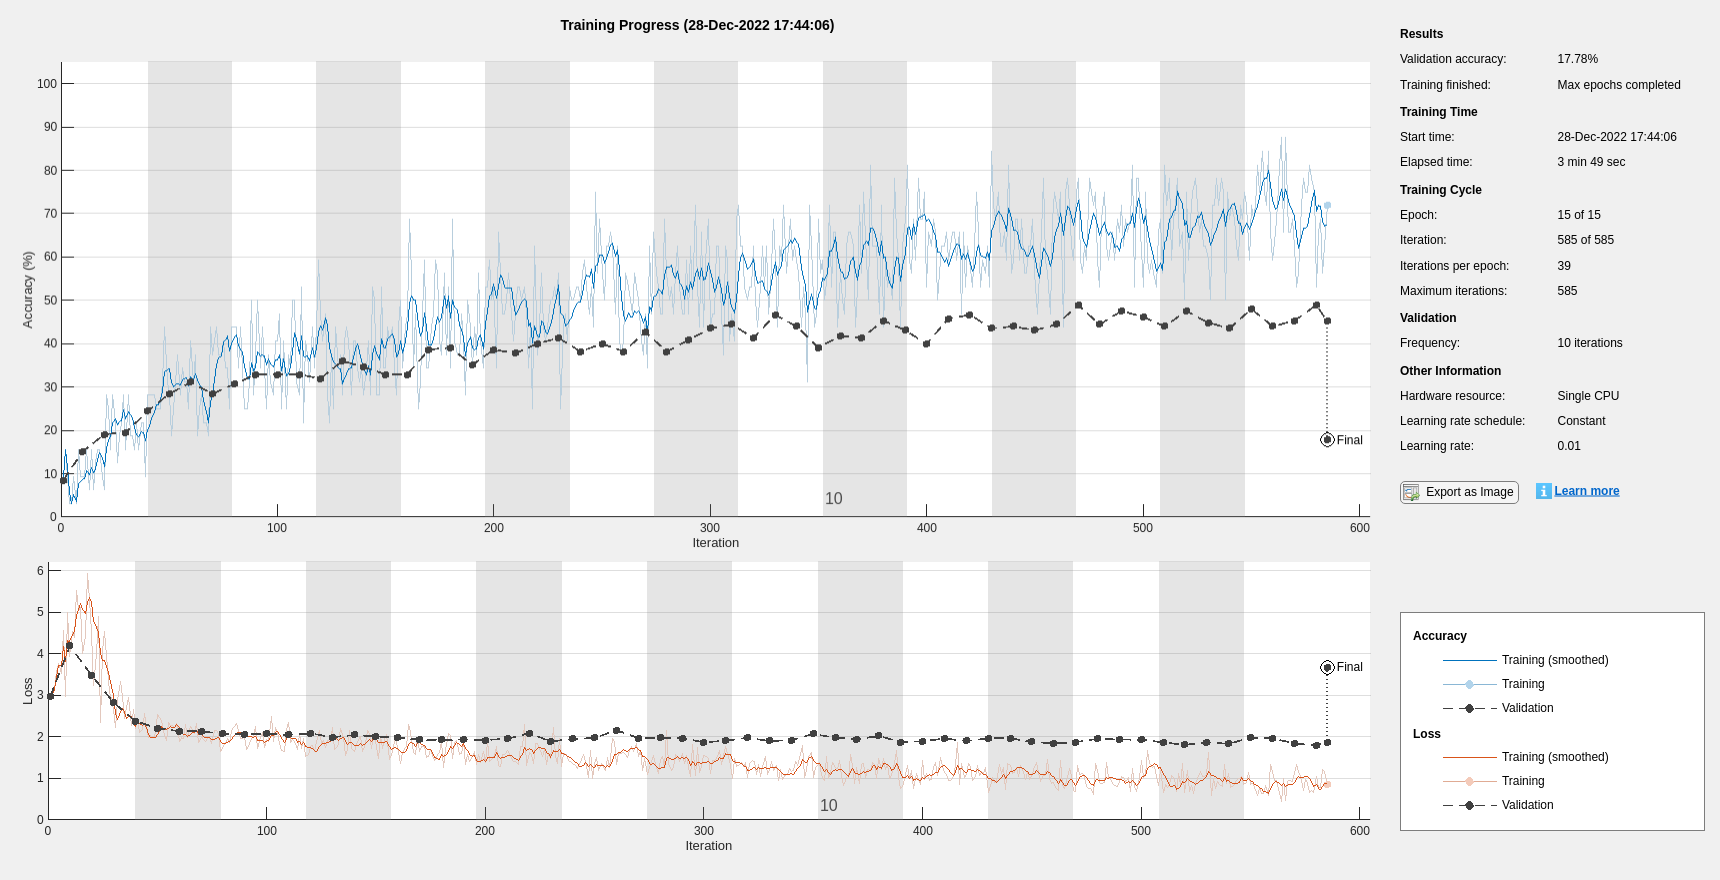


net_5 = trainNetwork(auimdsTrain,layers_4,options_3);


% apply the network to the test set
YPredicted = classify(net_5,imdsTest);
YTest = imdsTest.Labels;

% overall accuracy
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.2087

%To use an ensamble tecnique, we use the prevuous trained network and
%calculate the majority vote of the predictions

YPredicted0 = classify(net,imdsTest);
YPredicted1 = classify(net_1,imdsTest);
YPredicted2 = classify(net_2,imdsTest);
YPredicted3 = classify(net_3,imdsTest);
YPredicted4 = classify(net_4,imdsTest);

YPredictedMatrix = [YPredicted0 YPredicted1 YPredicted2 YPredicted3 YPredicted4];
YPredicted = mode(YPredictedMatrix, 2);
accuracy = sum(YPredicted == YTest)/numel(YTest)

accuracy = 0.5327